# Magnetic Circuit concepts

B = ?; % flux density (Wb/m^2 / T) 
u = ?; % permeability of the material

H = u*B; % field intensity 

To develop magnetic circuit analysis ,

let the amterial be linear

let the cross-sectional area expose to the magneitc flux density B grows to a nondifferential size ( any size that is fixed)


$$\phi =\int B_z \left(x,y\right)\;\textrm{dx}\;\textrm{dy}$$


or eaiser,

$\phi =\textrm{BA}$, where B is the constant flux density and A is the cross sectional area of the block

Once have the phi , 

stretching the block in the z-direction , the flux $\phi$flows through each succeeding layer of thickness creating a change in the magnetic field intensity 

$F=\int \textrm{Hdz}=\textrm{Hl}$, F magnetomotive force (A) , l the length of z (m)

## case 1 : box

A = ?;
phi = B * A;
F = H*l;


P = u*A/l; % permeance of the material
R = 1/P ; % reluctance 

phi = P * F ;


## Magnetic Field Sources

two common sources of magnetic fields : 

- current flowing in a wire

- permanent magnet

1) Current 


$$I=\oint_C H\ldotp \textrm{dl}$$
 

if C enclosed path or contour 

I is the total current enclosed by the contour

H . dl is the vecotr dot product between the vector field internsity and a differential vector dl on the contour 

Positive current is defined as flowiing in the direction of a right hand rule in the direction of the enclosed path 


$$I=\textrm{NI}=\int_a^b H_{\textrm{ab}} \textrm{dz}+\;\int_b^c H_{\textrm{bc}} \textrm{dr}+\int_c^d H_{\textrm{cd}\left(\right.} \left(-\textrm{dz}\right)+\int_d^a H_{\textrm{da}} \left(-\textrm{dr}\right)$$


## Air Gap Modelling



p_ag_model = '1';

u = 4*pi*10^-7; % permeability of free space (usually air )
g = ?; % air gap length
w = ?; % width
l = ?;

if p_ag_model =='1'
    
    A = w*l; % cross section area

    p_ga = u * A/g; % see below example a

elseif p_ag_model == '2'
    
    A = w*l + w*2*g;

    p_ga = u*(w*(l+2*g))/g; % see below example b

elseif p_ag_model == '3'

    A = w*l;

    P_s = u*A/g;

    func = @(x) u*L/(g+pi*x);
    Xmax = ; % no more than 10 times the gap length
    P_f = integral(func,0,Xmax);
    P_ga = Ps + P_f; % see below example c
end





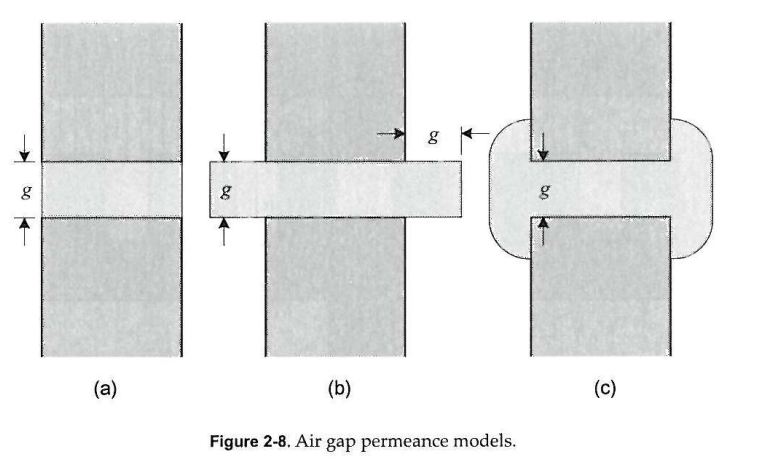

Better look of ©

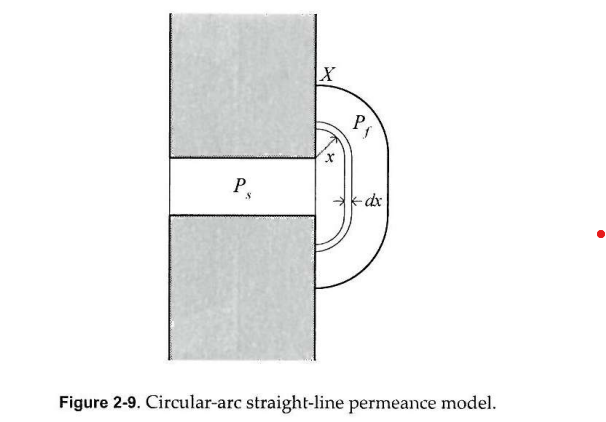

## Slot modelling

L = ?; % ldepth of the structureTs = ?; % total width
A = L*Ts; % cross section area (total width *  L)
g = ? ; % gap length
ws = ?;      % slot width in meters
tau_s = ?;      % slot pitch in meters
wt = tau_s  - ws ; % gap width in meters ( see below )

s_model = '1';
effective_gap_model = '1'
if s_model  == '1'

    Pg = u * A/g; 
    % a poor approximation because the relative 
    % permeability of the slot is orders of magnitude lower than that of block material
    % be the upper bound

elseif s_model == '2'
    L =  % this is the depth
    ws =  % slot gap
    Pg = u*(A-ws*L)/g;

    % ignore the flux crossing the gap over the slot 
    % lower bound the permeance 
elseif s_model == '3'

    % this method is based on the observation that the flux crossing the
    % gap over the slot travels a further distance before 
    % reaching the highly permeable material across the gap


    
    if effective_gap_model == '1'
        % Carter's coefficient - First approximation
        denom1 = tau_s * ((5 * g / ws + 1) / ws);
        Kc = 1 / (1 - 1 / denom1);  % equivalent to (1 - 1/denom1)^(-1)
    elseif effective_gap_model == '2'
        % Carter's coefficient - Second approximation
        term1 = ws / (2 * g);
        term2 = g / ws * log(1 + 0.25 * (ws / g)^2);
        Kc = 1 / (1 - (2 * ws / (pi * tau_s)) * (atan(term1) - term2));
    elseif effective_gap_model == '3'
        Kc = (1 - ws/tau_s + 4 * g/pi / tau_s * ln(1+ pi* ws/4/g))^(-1);
    end 

    % Effective air gap lengths
    ge = Kc * g;

    % Permeance
    Pg = u * A / ge;


end




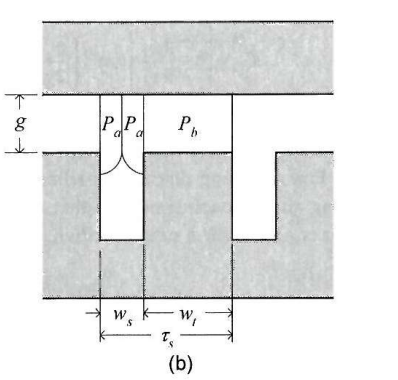

All K are correction factor . 

The increase of the factor , increase the slot percentage ( w_s/tau/_s)

The decrease of the factor , increase the gap length (g/tau/s).

When a permanent magnet across the air gap . the air gap length g in (mode 3) must be replaced by $g+\frac{l_m }{\mu_R }$

l_m is the magnet length , u_R is the magnet relative recoil permeability

More visualised image ,

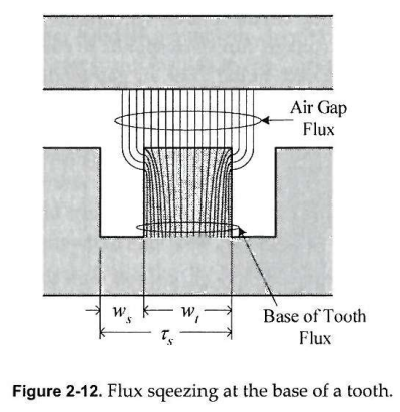

the presence of slots squeezes the air gap flux into a cross sectional area ( 1- w_s/tau_s)  times smaller than the cross-sectional area of the entrie air gap over one slot pitch.

Thus the average flux density at the base of the teeth is greater by a factor of (1-w_s/tau_s)^(-1)

## Magnetic Material


u_r = u/ u_o % relative permeability


% if u_r == 1 , the material is nonmagnetic material
% with greater u_r is magnetic material


Ferromagnetic mateials , or called eletrical steels , the most common magnetic mateirals used in motor construction.

Property:

- permeability of these materials is nonlinear and mutlivalued .

- saturating function of the field intensity and the multivalued nature of permeability means the flux density through the material is not unique for a given field intensity ( more easy way to interprety is that the saturating funciton means there is a limit of the flux apssing thorough),

- the flux density is a function of the past history of the field intensity

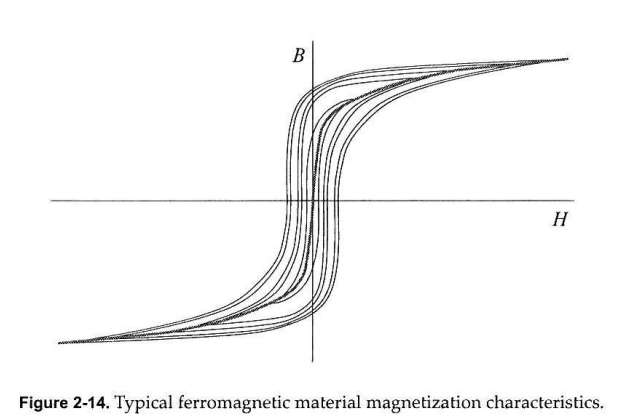

There is hysteresis loops meaning the excitation curve doesnot equal to the deexcitation . 

The loops are formed by applying sinusoidal excitation of different amplitudes to the material

with this curve there are two equation associated with 

syms H
B = ? ; % B is a function of H
u_o = ?;

u_d = simplify(diff(B,H)/ u_o);
mu_d = matlabFunction(u_d); % relative differential permeability

% small for low field intensity
% increase and peak at medium 
% decrease at high [saturation]
% or 

u_a = 1/u_o * B/H; % relative amplitude permeability



Core loss ( energy dissipated due to hysteresis and eddy current losses)

- hysteresis loop 

-     directly proportional to the size of the hysteresis loop of a given material 

-     proportional to the amplitude of the excitation


k_h = ?; % a constant depends on the material type and dimensions 
f = ?;   % frequency of applied excitation 
B = ?;   % flux density amplitude within the matieral
n = ?;   %material dependent exponenet between 1.5 and 2.5

P_h = k_h * f * B ^ n;


- Eddy current loss

-     caused by electrical currents induced within the ferromagnetic material under time varying excitation

h = ?;  % material thickness
k_e =?; % material dependent constant

P_e = k_e * h^2 * f^2 * B^2;


Then with these two loss , 

minimize eddy current loss :

- increase the resistivity of the mateirla by:

-         increase the presence of silicon 

-         stacking lamination together 

-         orient the laminations edges parallel to the desired flow of flux

-         decrease the lamination thickness ((proportional to the square of limation thickness)

But lamination decrease the amount of magnetic material availble to carry flux wthin a given cross-sectional area.

% Stacking factor
% ratio of the steel cross-sectional area to the total cross-sectional area
K_st = A_st/ A_total;

-         apply powdered ferromagnetic  [reduce eddy loss and allow for three dimensional flux flow]

-                 composed of powdered magnetic mateial suspended in a nonconductive resin

Use Sintered magnets 

sintering process allows magnets to be formed without a bonding agent 

The Best way to understand permanent magnet is hysteresis loop

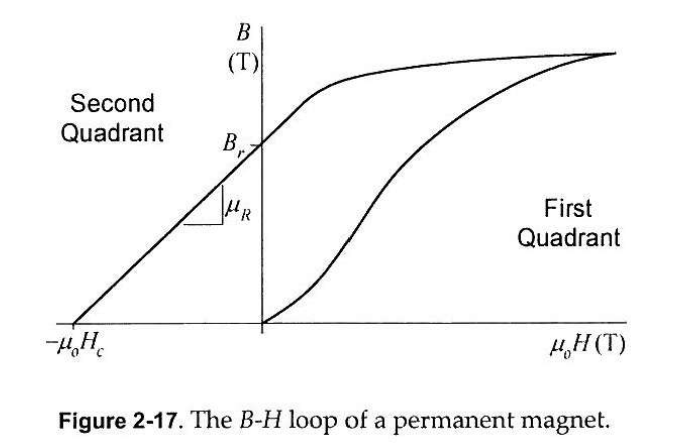

This loop is formed by applying the largest possible field intensity to an unmagnetized sample of material then shutting it off. This allow material to relax or recoil , along the upper curver. which called the demagnetized curve. Which is quadrant 2 . 

IF the configuration is shown like bleow figure (a) , the flux density leaving the magnet at this point is eqal to the remance of residual induction , denoted by Br , (remanence is the maximum flux density that the magnet ca produce by itself). Or if it has configuration like figure(b) , if u = 0 surround the matierla , no fluw flows out of the magnet so B = 0. Which arrive to -u * H_c point . At this point , the magnitude of the field intensity across the magnet is euqla to the negative of the coercivity or coercive force , denoted H_c.

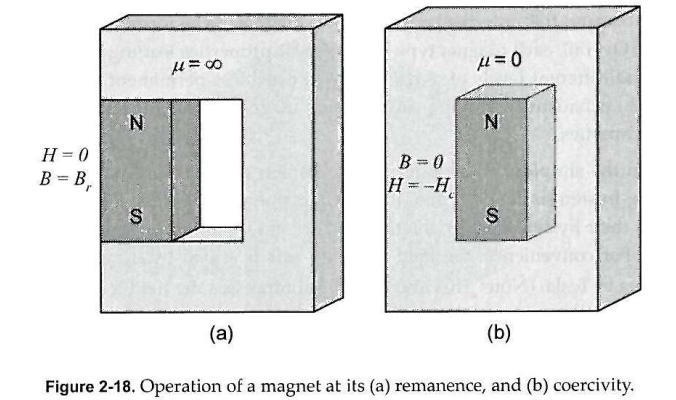

Another concept is permeance coefficient , denoted as $P_c$


$$P_c =\frac{B_{r/} }{H}$$


so if B = 0 then P_c is 0

if H = 0 then P_c = infinitiy

The slope of the demagnetisation curve is $u_r$.

Note: P_c refering to slope of the external load line . They are not the same thing.

The effect of temperature on the remanence $B_r$is approximately linear


$$B_r \left(T\right)=B_r \left(T_0 \right)\left\lbrack 1+\Delta_B \left(T-T_0 \right)\right\rbrack$$


T is the magnet temperature , T_0 is a reference tmeperature, 

B_R(T_0) is the remanence at T_0

delta_B is the reversible temperature coefficient

There are some material , that has a knee in the demagnetization characteristic around the second quadrant. Cause the flux density to drop off more quickly as -H_c is approached.

The operation will lead to the drop in effective B_r and H_c , lowering the overall performance.

So ** need to ensure the magnet operate away from the coercivity at a sufficiently large permeance coefficient P_c**

One last thing

## Maximum energy product (BH)_max

% the maximum product of the flux density and field intensity along the
% magnet demagnetization curve
% (qualitative measure of a magnet's performance capability in a mganetic cirucit)



Permanent Magnet Magnetic Circuit Model

B_m = B_r + u_R * u_0 * H_m;
% H_M is a negative quantity because of operation in second quadrant

% if the external magnetic field is considered when the external magnetic
% field opposes that developed by the magnet and drives the operating point
% into the third quadrant past the coercivity 

phi_r = B_r * A_m; % fixed flux source 


Pm = u_R * u_0 * A_m/I_m; % the permeance of the magnet, the magnet leakage 
%permeance 


phi = phi_r + P_m*F_m;
% where 





%B_m = B_r + u_R * u_o*H_m;
%
%phi = B_m*A_m ;


IF magnet shape differs from the rectangular shape , the magnet shape may appear as an arc

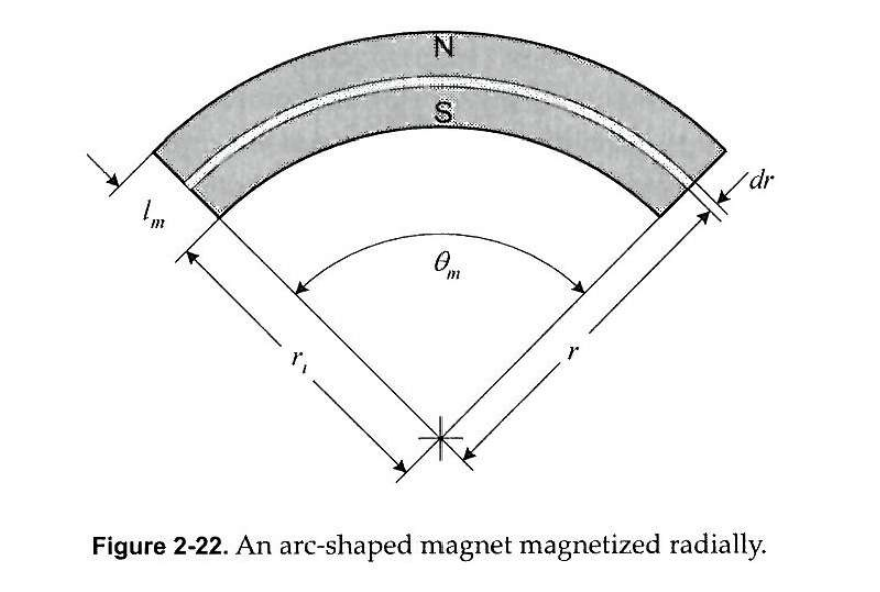


$$\mathrm{dR}=\frac{\mathrm{dl}}{\mathrm{uA}}=\frac{\mathrm{dr}}{u*r*\Theta_m *L}$$


L is the depth of the magnet into the page

% by integrating over R 

R_m = ln(1+l_m/r_i)/(u_r * u_o * L * theta_m)

P_m = 1/R_m;


% or if l_m << r_i
P_m = u_R * u_0*L*theta_m*r_i/l_m;